# Guía 2 - Ejercicio 1

## Enunciado

Implemente un perceptrón simple que aprenda la función lógica AND de 2 y 4 entradas. Lo mismo para la función lógica OR.

## AND 2 entradas:

clear all
close all
heta = 0.1;
w = rand([3 1])-0.5;
E=1;
x = [-1 -1  1;...
     -1  1  1;...
      1 -1  1;...
      1  1  1]';
Errores = [];
while E>0
    E = 0;
    orden = randperm(4);
    for i=1:4
        if x(1,orden(i)) == 1 && x(2,orden(i)) == 1
            y_deseado = 1;
        else
            y_deseado=-1;
        end
        y = sign(w'*x(:,orden(i)));
        DeltaW= heta*x(:,orden(i))*(y_deseado-y);
        w=w+DeltaW;
        E = E+ 1/2*(y_deseado-y)^2;
    end
    Errores = [Errores E];
end
w

w =     0.3822
    0.2083
   -0.2660


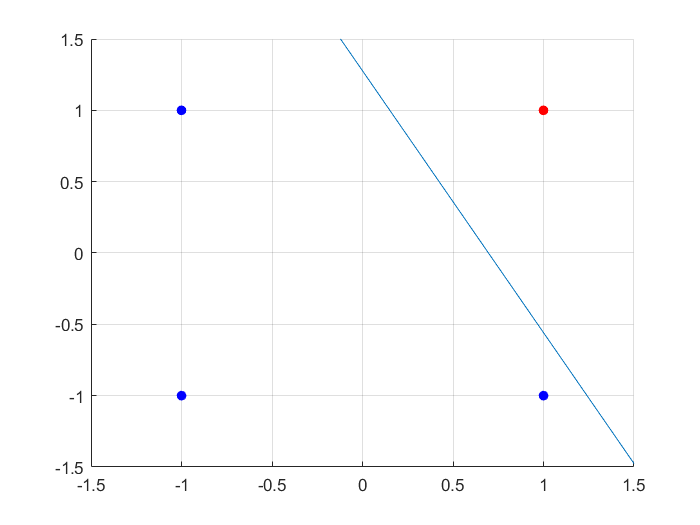

close all
figure(1)
hold on
plot((-1.5:0.1:1.5), -(w(3)/w(2))-(w(1)/w(2))*(-1.5:0.1:1.5))
axis([-1.5 1.5 -1.5 1.5])
plot(1,1,'.r', 'MarkerSize',20)
plot(1,-1,'.b', 'MarkerSize',20)
plot(-1,1,'.b', 'MarkerSize',20)
plot(-1,-1,'.b', 'MarkerSize',20)
grid on

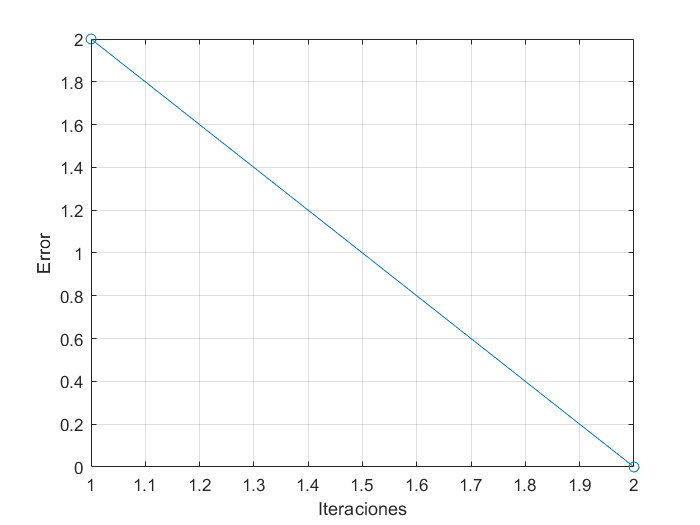

figure(2)
plot(Errores,'-o')
grid on
xlabel('Iteraciones')
ylabel('Error')

## AND 4 entradas:

heta = 0.1;
w = rand([5 1])-0.5;
E=1;
x = [-1 -1 -1 -1  1 ;...
     -1 -1 -1  1  1 ;...
     -1 -1  1 -1  1 ;...
     -1 -1  1  1  1 ;...
     -1  1 -1 -1  1 ;...
     -1  1 -1  1  1 ;...
     -1  1  1 -1  1 ;...
     -1  1  1  1  1 ;...
      1 -1 -1 -1  1 ;...
      1 -1 -1  1  1 ;...
      1 -1  1 -1  1 ;...
      1 -1  1  1  1 ;...
      1  1 -1 -1  1 ;...
      1  1 -1  1  1 ;...
      1  1  1 -1  1 ;...
      1  1  1  1  1 ]';
Errores = [];
while E>0
    E = 0;
    orden = randperm(16);
    for i=1:16
        if (x(1,orden(i)) ==1) &&(x(2,orden(i)) == 1)&&(x(3,orden(i)) == 1)&&(x(4,orden(i)) == 1)
            y_deseado = 1;
        else
            y_deseado=-1;
        end
        y = sign(w'*x(:,orden(i)));
        DeltaW= heta*x(:,orden(i))*(y_deseado-y);
        w=w+DeltaW;
        E = E+ 1/2*(y_deseado-y)^2;
    end
    Errores = [Errores E];
end
sign(w'*x)

ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1


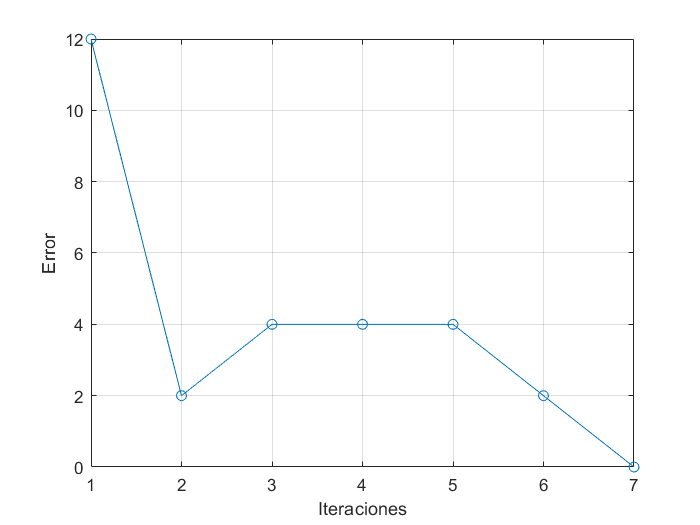

figure(2)
plot(Errores,'-o')
grid on
xlabel('Iteraciones')
ylabel('Error')

## OR 2 entradas:

heta = 0.1;
w = rand([3 1])-0.5;
E=1;
x = [-1 -1 1; -1 1 1; 1 -1 1; 1 1 1]';

Errores = [];
while E>0
    E = 0;
    orden = randperm(4);
    for i=1:4
        if (x(1,orden(i)) ==1) || (x(2,orden(i)) == 1)
            y_deseado = 1;
        else
            y_deseado=-1;
        end
        y = sign(w'*x(:,orden(i)));
        DeltaW= heta*x(:,orden(i))*(y_deseado-y);
        w=w+DeltaW;
        E = E+ 1/2*(y_deseado-y)^2;
    end
    Errores = [Errores E];

end
w

w =     0.2461
    0.3519
    0.3013


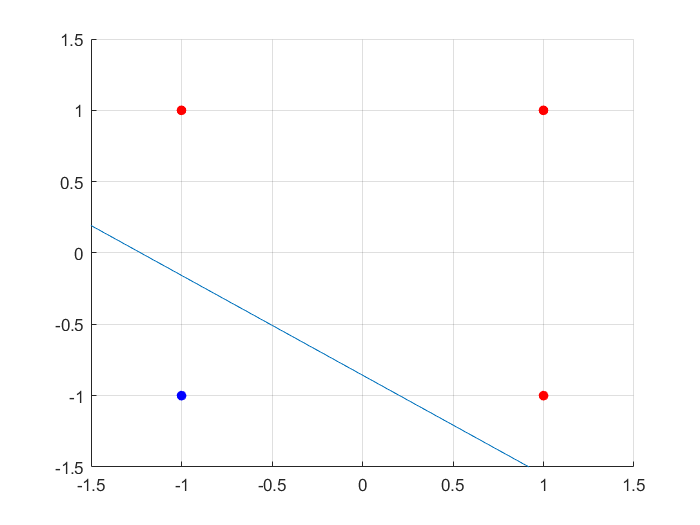

close all
figure(1)
hold on
plot((-1.5:0.1:1.5), -(w(3)/w(2))-(w(1)/w(2))*(-1.5:0.1:1.5))
axis([-1.5 1.5 -1.5 1.5])
plot(1,1,'.r', 'MarkerSize',20)
plot(1,-1,'.r', 'MarkerSize',20)
plot(-1,1,'.r', 'MarkerSize',20)
plot(-1,-1,'.b', 'MarkerSize',20)
grid on

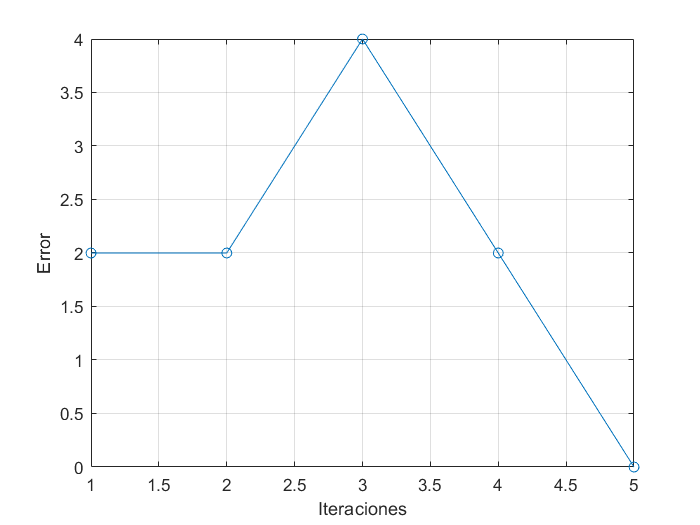

figure(2)
plot(Errores,'-o')
grid on
xlabel('Iteraciones')
ylabel('Error')

## OR 4 entradas:

heta = 0.1;
w = rand([5 1])-0.5;
DeltaW=0;
y_deseado=1;
E=1;
x = [-1 -1 -1 -1  1 ;...
     -1 -1 -1  1  1 ;...
     -1 -1  1 -1  1 ;...
     -1 -1  1  1  1 ;...
     -1  1 -1 -1  1 ;...
     -1  1 -1  1  1 ;...
     -1  1  1 -1  1 ;...
     -1  1  1  1  1 ;...
      1 -1 -1 -1  1 ;...
      1 -1 -1  1  1 ;...
      1 -1  1 -1  1 ;...
      1 -1  1  1  1 ;...
      1  1 -1 -1  1 ;...
      1  1 -1  1  1 ;...
      1  1  1 -1  1 ;...
      1  1  1  1  1 ]';
  
Errores = [];
while E>0
    E = 0;
    orden = randperm(16);
    for i=1:16
        if (x(1,orden(i)) ==1) ||(x(2,orden(i)) == 1)||(x(3,orden(i)) == 1)||(x(4,orden(i)) == 1)
            y_deseado = 1;
        else
            y_deseado=-1;
        end
        y = sign(w'*x(:,orden(i)));
        DeltaW= heta*x(:,orden(i))*(y_deseado-y);
        w=w+DeltaW;
        E = E+ 1/2*(y_deseado-y)^2;
    end
    Errores = [Errores E];

end
sign(w'*x)

ans =     -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


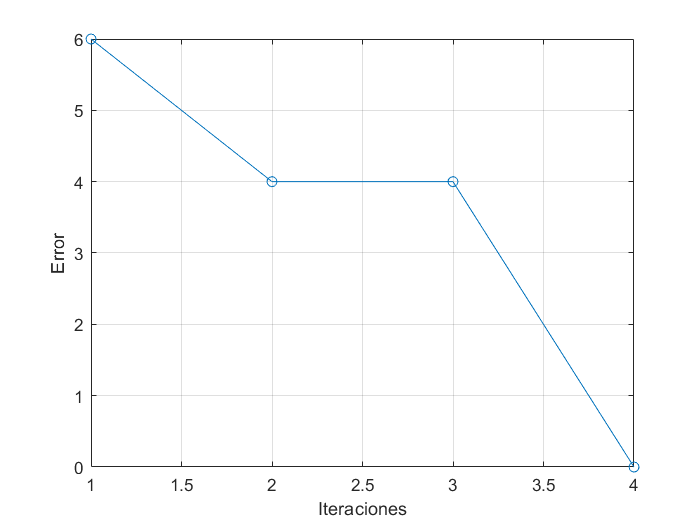

figure(2)
plot(Errores,'-o')
grid on
xlabel('Iteraciones')
ylabel('Error')